Question 2

(a),(b) Random samples distributed according to$f\left(x\right)$using the acceptance-rejection method with $g\left(x\right)=0\ldotp 3\;\forall x\in \left\lbrack 0,10\right\rbrack$ where


$$f\left(x\right)=\frac{1}{1000}\left(100+\frac{4}{5}x^3 -6x^2 \right)$$


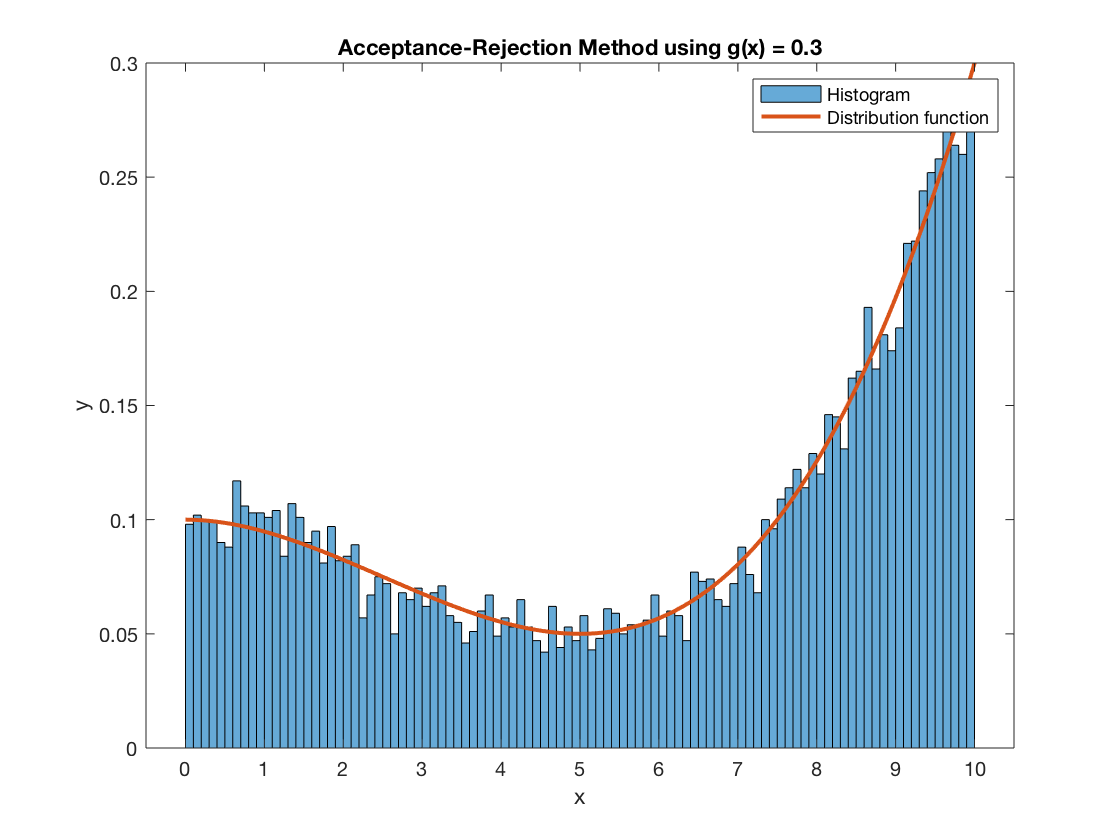

clear 
clc 

%Call function, save values and plot histogram
[samples, accepted, total] = acceptedsamples(10000);
histogram(samples,100,"Normalization","pdf")

hold on 

%Plot pdf
t = 0:0.1:10;
F = (100+4/5*power(t,3)-6*power(t,2))/1000;
plot(t,F,"linewidth",2)

title('Acceptance-Rejection Method using g(x) = 0.3')
xlabel('x')
ylabel('y')
legend('Histogram','Distribution function')

hold off

rejectionrate = (1- accepted/total)*100

rejectionrate =   66.469976866597378


(c), (d) Notice$f\left(x\right)$has local minima in the interval $\left\lbrack 0,10\right\rbrack$. To find the local minima, we can calculate the derivative and set it to zero


$$f^{\prime } \left(x\right)=\frac{1}{1000}\left(\frac{4}{5}\ldotp 3x^2 -6\ldotp 2x\right)=0$$



$$\Rightarrow \;\frac{12}{5\ldotp 1000}x^2 -12x=0$$



$${\Rightarrow \;x}^2 -5x=0$$



$$\Rightarrow \;x=0,5$$


We need to find a function of the form 

   
$$g\left(x\right)=a+{b\left(x-5\right)}^2$$


with the appropriate variable *a *and *b *such the $g\left(x\right)\le f\left(x\right)\;\forall \;x\in \left\lbrack 0,10\right\rbrack$. 

Notice since g is quadratic polynomial, it has a global minima and it's found at $x=5$. To find the optimal values of a and b for the acceptance-rejection method, we need to minimize the area between f and g. We can do this by

- Setting $f\left(5\right)=g\left(5\right)$ to find a. This will make $g\left(x\right)$and$f\left(x\right)$coincide at $x=5$

- Setting $f\left(10\right)=g\left(10\right)$ to find $b$ so that we can stretch $g$ just enough 

By doing this, we get 

$a=f\left(5\right)=0\ldotp 05$ and $b=0\ldotp 01$

An illustration of this would be:

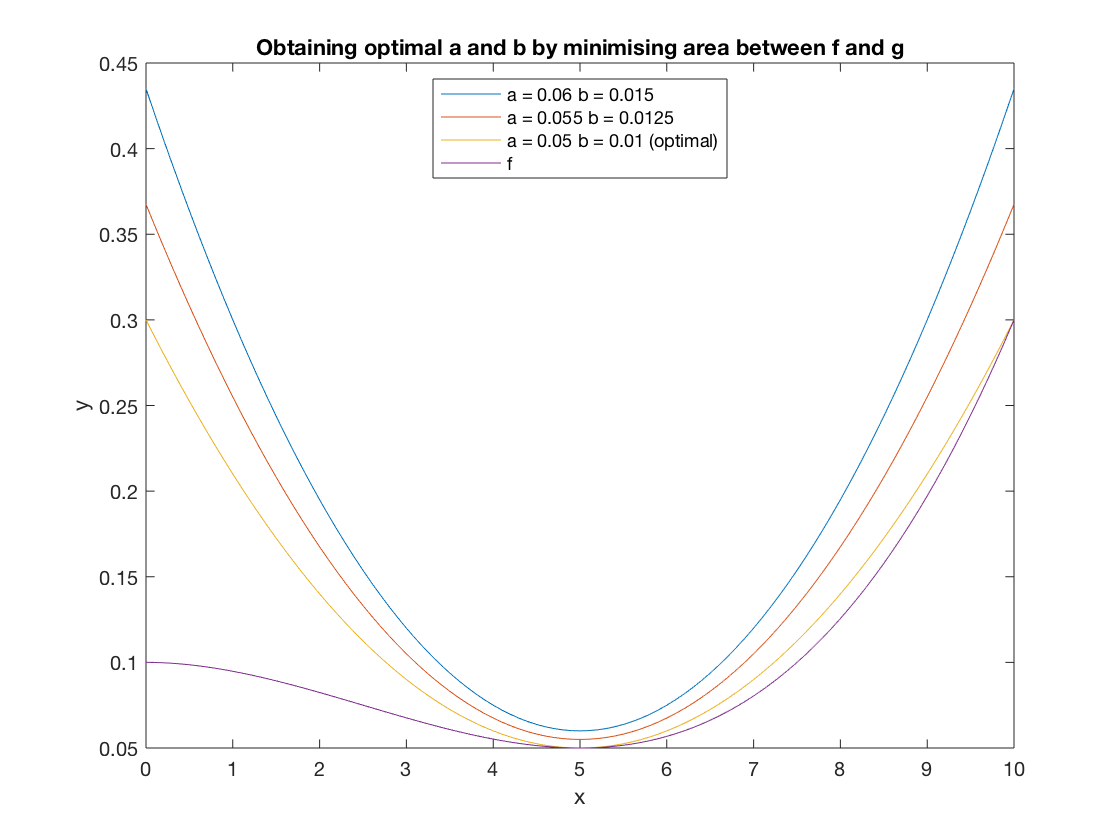

clear
clc

g1 = @(x) 0.05 + 0.01*power(x-5,2);
g2 = @(x) 0.055 + 0.0125*power(x-5,2);
g3 = @(x) 0.06 + 0.015*power(x-5,2);

f = @(x) 0.001*(100 + 0.8*power(x,3) - 6*power(x,2));

x = 0:0.1:10;

plot(x, g3(x), x, g2(x), x, g1(x), x, f(x))
title('Obtaining optimal a and b by minimising area between f and g')
xlabel('x')
ylabel('y')
legend('a = 0.06 b = 0.015','a = 0.055 b = 0.0125', 'a = 0.05 b = 0.01 (optimal)','f',"location","north")

Clearly $g\left(x\right)\le f\left(x\right)\;\mathrm{in}\;\left\lbrack 0,10\right\rbrack \;a=0\ldotp 05\;\mathrm{and}\;b=0\ldotp 01$. Hence now we can go ahead and execute our algorithm. For the algorithm, we need the following 


$$g\left(x\right)=a+{b\left(x-5\right)}^2$$



$$\Rightarrow A_g =\int_0^{10} g\left(x\right)=10a+\frac{500}{6}b$$


Hence the required CDF is 


$$\mathrm{CDF}=\int_0^x g\left(t\right)/A_g \;dt$$



$$\Rightarrow \mathrm{CDF}=\frac{\left(\mathrm{ax}+{\mathrm{bx}}^3 /2+25\mathrm{bx}-5x^2 b\right)}{10a+\frac{500}{6}b}$$


Using WolframAlpha, we get the inverse of the CDF


$${\mathrm{CDF}}^{-1} \;=\;-5^{\frac{1}{3}} {\left(\sqrt{5}\sqrt{320*x^2 -320x+81}-40x+20\right)}^{\frac{1}{3}} +\frac{5^{\frac{2}{3}} }{{\left(\sqrt{5}\sqrt{320*x^2 -320x+81}-40x+20\right)}^{\frac{1}{3}} }+5;$$


Using this, we create the required function 

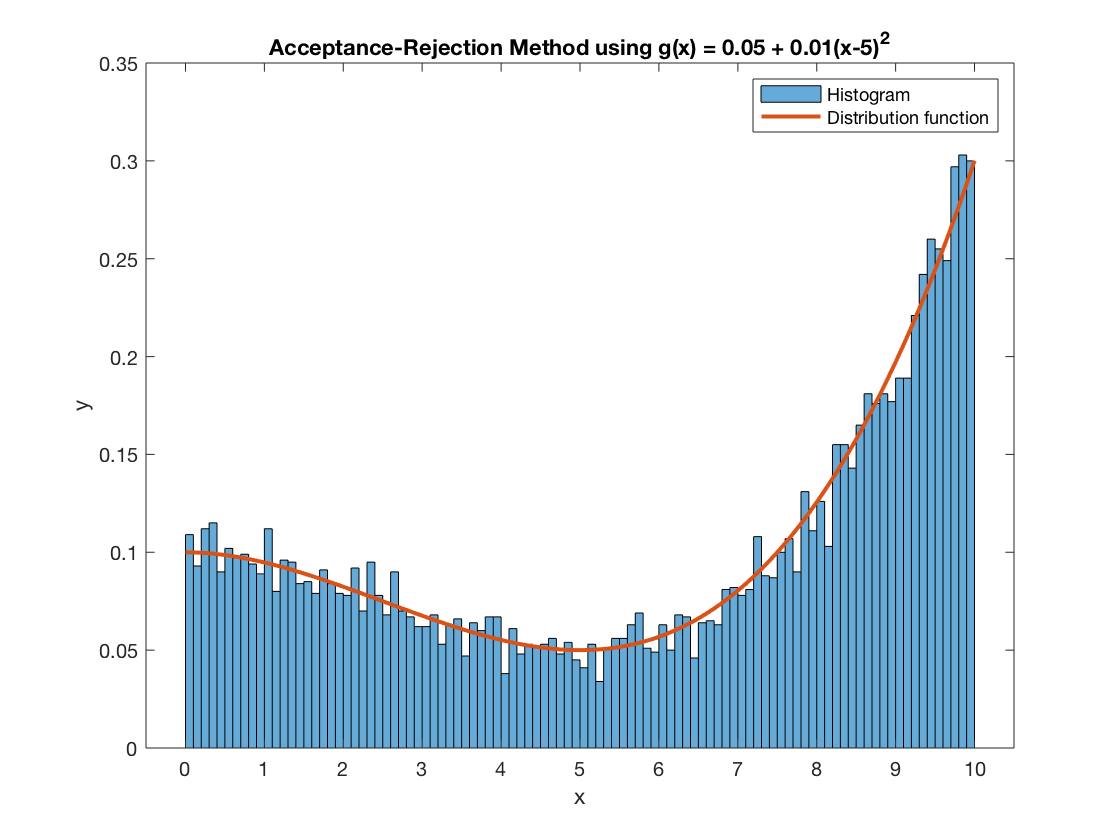

[samples, accepted, total] = acceptedsamples2(10000);
histogram(samples,100,"Normalization","pdf")

hold on 

%Plot pdf
t = 0:0.1:10;
F = (100+4/5*power(t,3)-6*power(t,2))/1000;
plot(t,F,"linewidth",2)
title('Acceptance-Rejection Method using g(x) = 0.05 + 0.01(x-5)^2')
xlabel('x')
ylabel('y')
legend('Histogram','Distribution function')

rejectionrate = (1- accepted/total)*100

rejectionrate =   23.935199269850926


Functions

function [samples,accepted,total] = acceptedsamples(N)
    
    g = 0.3;
    Ag = 3;
    cutoff = g/Ag;
    
    % Accepted Samples
    accepted = 1;
    %Total Samples
    total = 1;
    
    while accepted <= N
    
        % Sample a random variable x from the probability density function g(x)/Ag using the Inverse Function method
        xbar = 1/cutoff*rand;
        % Sample a random variable y uniformly in [0, g(x)]
        ybar = g*rand;
        f = (100 + 4/5*power(xbar,3) - 6*power(xbar,2))/1000;
        
        % If y ≤ f(x) then accept the sample and return x. Otherwise, reject
        if f >= ybar 
            samples(accepted) = xbar; 
            accepted=accepted+1;
        end
        total = total + 1;
    end 

end

function [samples, accepted, total] = acceptedsamples2(N)
        
    accepted = 1;
    total= 1;
    
    while accepted <= N
    
        % Sample a random variable x from the probability density function g(x)/Ag using the Inverse Function method
        x = rand;
        xbar = -5^(1/3)*(sqrt(5)*sqrt(320*x^2 - 320*x + 81) - 40*x + 20)^(1/3) + 5^(2/3)/(sqrt(5)*sqrt(320*x^2 - 320*x + 81) - 40*x + 20)^(1/3) + 5;     
        % Sample a random variable y uniformly in [0, g(x)]
        g = 0.05 + 0.01*power(xbar-5,2);
        ybar = g*rand;
        f = (100 + 4*power(xbar,3)/5 -6*power(xbar,2))/1000;
        % If y ≤ f(x) then accept the sample and return x. Otherwise, reject
        if f >= ybar 
            samples(accepted) = xbar; 
            accepted=accepted+1;
        end
        total  = total + 1;
    end 
end